clc
clear
close all

# Generate Signal

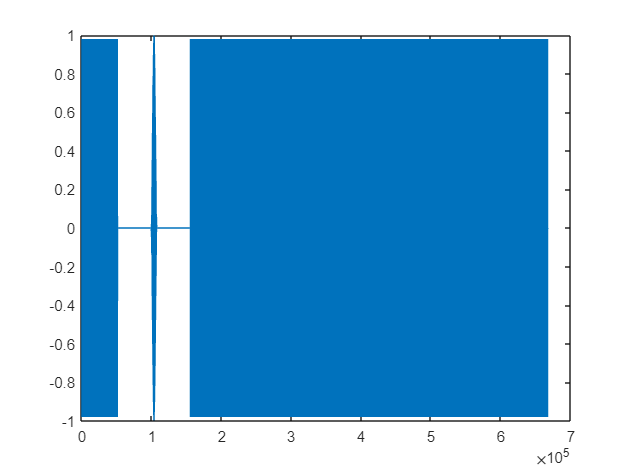

fs = 48e3;            % 采样率
chirpLen = 256;       % 单个 chirp 信号的长度
T = chirpLen / fs;    % 单个 chirp 周期的时间
t = linspace(0, T, fs * T); % 时间向量
N_rep = 1000;         % chirp 信号的重复次数

f0 = 18e3;            % 起始频率
f1 = 22e3;            % 终止频率

% 生成 chirp 信号
chirp0 = chirp(t, f0, T, f1);

% 创建一个 chirp 周期的帧并将其与零填充拼接
frame = [chirp0 .* hanning(chirpLen)' zeros(1, length(chirp0))];

N_seg = 8192;         % Chirp 信号的长度

t_seg = (0:N_seg-1) / fs; % 时间序列

% 生成 chirp 信号
flag = chirp(t_seg, f1, t_seg(end), f0) .* hanning(N_seg)';

% 构建一个包含多个信号的通道 channel1
channel1=[repmat(frame,1,100),zeros(1,fs),flag,zeros(1,fs),repmat(frame,1,N_rep)];

% 创建一个与 channel1 等长的空信号 channel2
channel2 = zeros(1, length(channel1));

% 将左声道的音频数据映射到 [-32767, 32767] 范围，并将其转换为 int16 类型
pcm_data_left = int16(channel1 * 32767);

% 将右声道的音频数据映射到 [-32767, 32767] 范围
pcm_data_right = channel2;

% 输出文件名
output_filename = 'C_FMCW_Play.pcm';

% 打开二进制文件以写入数据
fid = fopen(output_filename, 'wb');

% 将左右声道的数据写入文件，数据类型为 int16
fwrite(fid, [pcm_data_left; pcm_data_right], 'int16');

% 关闭文件
fclose(fid);

% 绘制 channel1 的波形
figure
plot(channel1)

# Receive signal

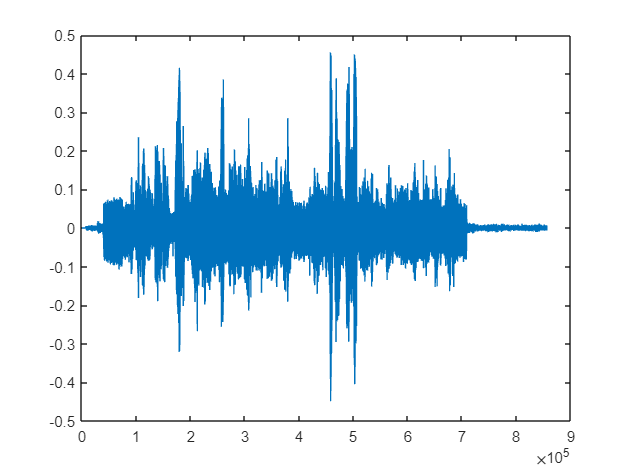

% 从PCM文件中读取立体声音频数据，并进行归一化
data = pcmread_stereo('./test4.pcm') / 2^15;

% 创建一个新的图形窗口，绘制左声道的原始数据
figure
plot(data(:, 1))


% 设计一个带通滤波器
[b, a] = butter(5, [17e3/(fs/2) 23e3/(fs/2)], 'bandpass');

% 使用滤波器对左声道的数据进行滤波
rec = filter(b, a, data(:, 1));

# Synchronization

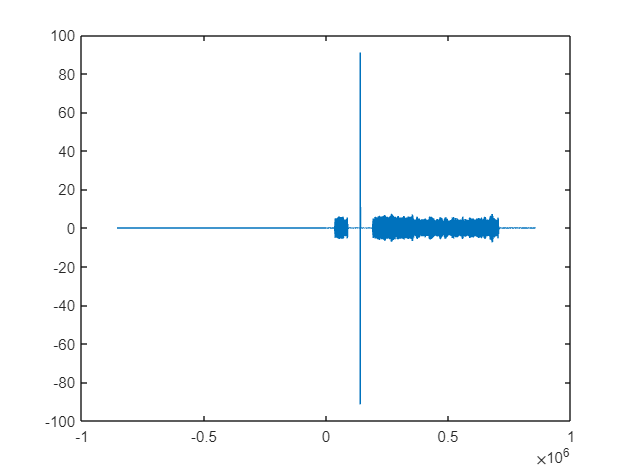

% 计算接收信号 rec 与 flag 信号的互相关
[f, l] = xcorr(rec, flag);  % 互相关

% 创建一个新的图形窗口
figure

% 绘制互相关函数 f 随滞后 l 的变化
plot(l, f)


% 找到互相关函数的最大值对应的滞后值
idx = l(f == max(f));

# C-FMCW

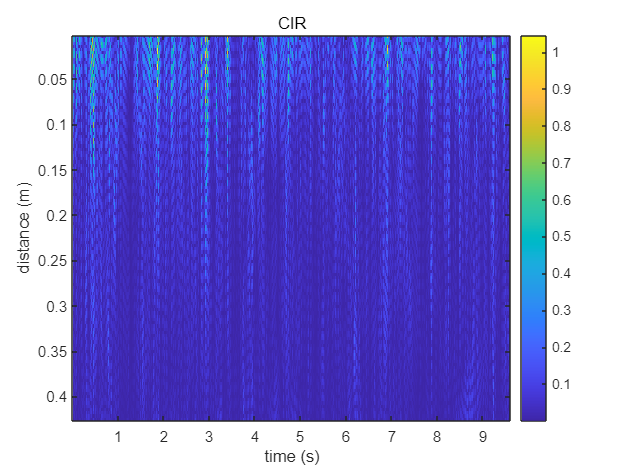

% 计算起始索引，考虑到滞后和 flag 的长度以及一个周期的采样数
start_index = idx + length(flag) + fs;

% 初始化一个矩阵来存储信道脉冲响应（CIR）
CIR = zeros(511, N_rep - 100);

for i = 1:N_rep - 100
    % 计算当前和前一个周期的信号差异
    offset_pre = (i - 1) * 512;
    pre = rec(offset_pre + start_index : offset_pre + length(chirp0) + start_index - 1);
    
    offset_cur = i * 512;
    cur = rec(offset_cur + start_index : offset_cur + length(chirp0) + start_index - 1);
    
    sig = cur - pre;

    % 计算信道脉冲响应（CIR）
    CIR(:, i) = abs(conv(sig, flip(chirp0)));
end

% 创建一个新的图形窗口
figure

% 创建 x 和 y 轴向量
x = (1:900) * 512 / fs; % 时间轴
y = (1:120) * (170 / fs); % 距离轴

% 绘制信道脉冲响应（CIR）的热力图
imagesc(x, y, CIR(257:257+119, :))

% 添加颜色条
colorbar

% 设置图形标题
title("CIR")
% 设置 X 轴标签
xlabel('time (s)')
% 设置 Y 轴标签
ylabel('distance (m)')

# Distance Change

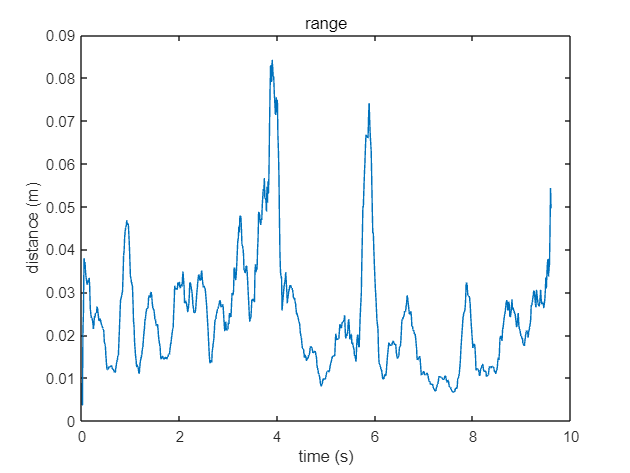

% 从CIR矩阵中提取最大值及其对应的距离
[M, distance] = max(CIR(257:257+119, :), [], 1);

% 将距离转换为实际距离（米）
real_d = distance * (170 / fs);

% 应用Hampel滤波器以去除异常值
real_d = hampel(real_d, 20);

% 平滑处理距离数据
real_d = smooth(real_d, 20);

% 创建一个新的图形窗口
figure

% 创建x轴向量（时间）
x = (1:N_rep - 100) * 512 / fs;

% 绘制实际距离随时间的变化
plot(x, real_d)

% 设置图形标题
title('range')
% 设置X轴标签
xlabel('time (s)')
% 设置Y轴标签
ylabel('distance (m)')